# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
for i = 2:length(SIDS)
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

sid = 0b5a2ePlayback

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =    1.0e-28 *

    0.1516
         0
    0.0000


tbl =     'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'             'Prob>F'    
    'anovaNumStims'                 [  638.4524]    [   3]    [        0]    [  212.8175]    [   46.0531]    [1.5160e-29]
    'anovaBetaSID'                  [7.6538e+04]    [   7]    [        0]    [1.0934e+04]    [2.3661e+03]    [         0]
    'anovaNumStims*anovaBetaSID'    [1.0910e+03]    [  21]    [        0]    [   51.9540]    [   11.2427]    [8.1694e-38]
    'Error'                         [4.5324e+04]    [9808]    [        0]    [    4.6211]              []              []
    'Total'                         [1.6811e+05]    [9839]    [        0]              []              []              []


stats =          source: 'anovan'
          resid: [9840x1 double]
         coeffs: [45x1 double]
            Rtr: [32x32 double]
       rowbasis: [32x45 double]
            dfe: 9808
            mse: 4.6211
    nullproject: [45x32 double]
          terms: [3x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [4x1 double]
     coeffnames: {45x1 cell}
           vars: [45x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


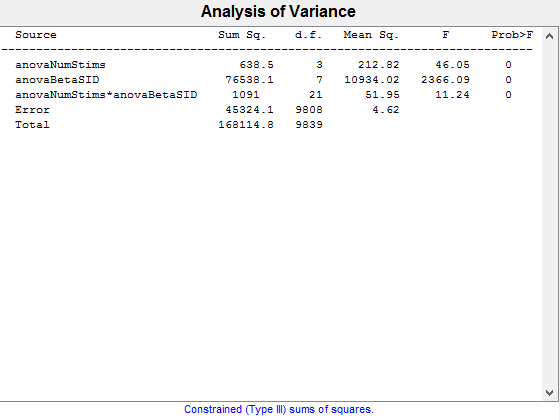

figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'model','interaction','varnames',{'anovaNumStims','anovaBetaSID'})

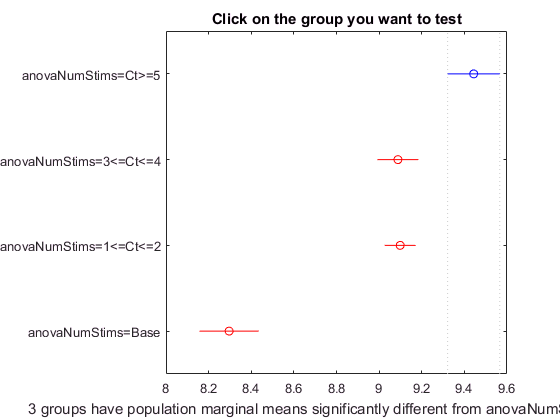

c =     1.0000    2.0000    0.1351    0.3557    0.5762    0.0002
    1.0000    3.0000    0.1489    0.3451    0.5413    0.0000
    1.0000    4.0000    0.8893    1.1476    1.4060    0.0000
    2.0000    3.0000   -0.1766   -0.0106    0.1555    0.9984
    2.0000    4.0000    0.5557    0.7920    1.0282    0.0000
    3.0000    4.0000    0.5889    0.8025    1.0162    0.0000


m =     9.4437    0.0672
    9.0881    0.0534
    9.0986    0.0363
    8.2961    0.0748


h =   Figure (41: Multiple comparison of population marginal means) with properties:

      Number: 41
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [9.4437]    [0.0672]
    'anovaNumStims=3<=Ct<=4'    [9.0881]    [0.0534]
    'anovaNumStims=1<=Ct<=2'    [9.0986]    [0.0363]
    'anovaNumStims=Base'        [8.2961]    [0.0748]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8.2000 9.6000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8.2000 9.6000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'>5','3->4', '1->2','Baseline'}

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8.2000 9.6000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


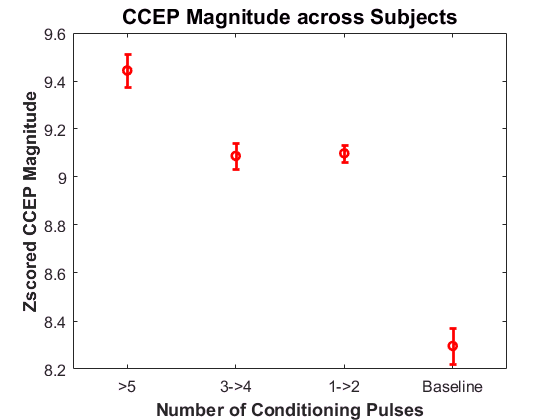

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

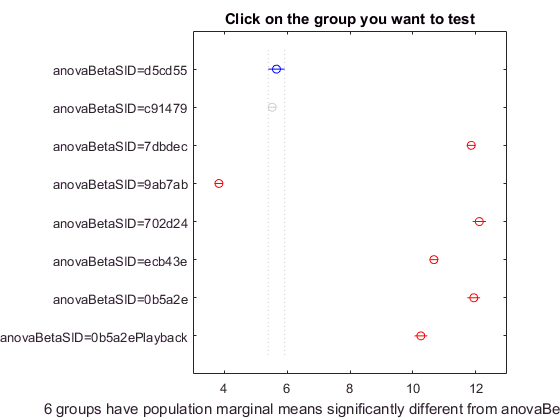

results1 =     1.0000    2.0000   -0.2658    0.1368    0.5393    0.9700
    1.0000    3.0000   -6.6151   -6.2034   -5.7918    0.0000
    1.0000    4.0000    1.4389    1.8339    2.2289    0.0000
    1.0000    5.0000   -6.9248   -6.4600   -5.9952    0.0000
    1.0000    6.0000   -5.4253   -5.0137   -4.6021    0.0000
    1.0000    7.0000   -6.7425   -6.2850   -5.8274    0.0000
    1.0000    8.0000   -5.0563   -4.5988   -4.1412    0.0000
    2.0000    3.0000   -6.6158   -6.3402   -6.0646    0.0000
    2.0000    4.0000    1.4471    1.6971    1.9472    0.0000
    2.0000    5.0000   -6.9468   -6.5968   -6.2468    0.0000



figure
results1 = multcompare(stats,'Dimension',[2])

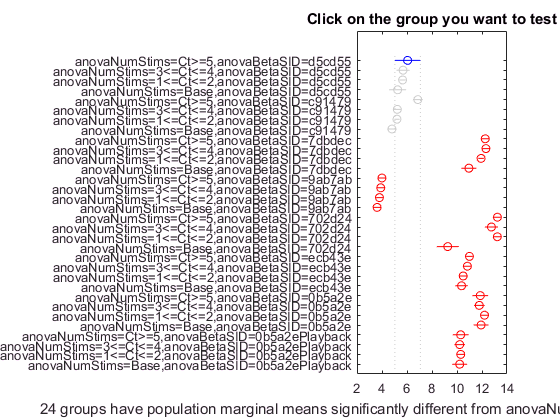

cM =     1.0000    2.0000   -1.1251    0.3668    1.8587    1.0000
    1.0000    3.0000   -0.9390    0.4031    1.7451    1.0000
    1.0000    4.0000   -0.7949    0.7988    2.3925    0.9931
    1.0000    5.0000   -2.2278   -0.8135    0.6008    0.9541
    1.0000    6.0000   -0.5560    0.8244    2.2048    0.9291
    1.0000    7.0000   -0.4730    0.8505    2.1740    0.8512
    1.0000    8.0000   -0.1486    1.2544    2.6574    0.1714
    1.0000    9.0000   -7.5585   -6.2054   -4.8522    0.0000
    1.0000   10.0000   -7.6235   -6.2638   -4.9040    0.0000
    1.0000   11.0000   -7.2023   -5.8744   -4.5464    0.0000


mM =     6.0500    0.3442
    5.6832    0.1930
    5.6470    0.0869
    5.2512    0.2434
    6.8635    0.1466
    5.2256    0.1219
    5.1995    0.0639
    4.7956    0.1388
   12.2554    0.0982
   12.3138    0.1044


hM =   Figure (55: Multiple comparison of population marginal means) with properties:

      Number: 55
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaBetaSID=d5cd55'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=d5cd55'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=d5cd55'
    'anovaNumStims=Base,anovaBetaSID=d5cd55'
    'anovaNumStims=Ct>=5,anovaBetaSID=c91479'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=c91479'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=c91479'
    'anovaNumStims=Base,anovaBetaSID=c91479'
    'anovaNumStims=Ct>=5,anovaBetaSID=7dbdec'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=7dbdec'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=7dbdec'
    'anovaNumStims=Base,anovaBetaSID=7dbdec'
    'anovaNumStims=Ct>=5,anovaBetaSID=9ab7ab'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=9ab7ab'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=9ab7ab'
    'anovaNumStims=Base,anovaBetaSID=9ab7ab'
    'anovaNumStims=Ct>=5,anovaBetaSID=702d24'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=702d24'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=702d24'
    'anovaNumStims=Base,anovaBetaSID=702d24'
    'anovaNumStims=Ct>=5,anovaBetaSID=ecb43e'



% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')
